Start Here

Step 0: Netlist Graph

 
%Create EdgeTable.
s = [1 2 3];
t = [2 3 1];
weights = [1 1 1]';
maximum_distance = [5 6 7]';
minimum_distance = [1 2 3]';
actual_distance = [4 5 6]';
net = {'Net1' 'Net2' 'Net3'}';
code = {'Component1Terminal2 Component2Terminal1'...
    'Component2Terminal2 Component3Terminal1'...
    'Component3Terminal2 Component1Terminal1'}';
EdgeTable = table([s' t'],weights,code, maximum_distance, ...
    maximum_distance, net, 'VariableNames',{'EndNodes' 'Weight' ...
    'code' 'maximum_distance' 'minimum_distance' 'Net'});
%Create NodeTable
names = {'Component1' 'Component2' 'Component3'}';
node_codes = {'1' '2' '3'}';
NodeTable = table(names,node_codes,'VariableNames',{'Component' 'ID'});
G = digraph(EdgeTable,NodeTable);
fontsize = 20;
plot(G,'NodeLabel',G.Nodes.Component,'EdgeLabel',G.Edges.code, 'EdgeFontSize',fontsize, 'NodeFontSize',fontsize);
title('Terminal Graph', 'FontSize',fontsize)
FastHenryAutomationDirectory = 'C:\Users\Public\Documents\FastFieldSolvers\FastHenry2\Automation\Office\';

routingOrder = [3, 2, 1];
proj = currentProject;
ProjectDirectory = proj.RootFolder;

filePath = 'data/gaEnsemble';
allFiles = dir( filePath );
allNames = { allFiles.name };
seqPair_Folders = allNames(3:end-1);
% fileIndex = 33; %<- Tested. Corner Hole Bug detected(FileI 4, Component 2 up 1, Component 3 left 1.)
fileIndex = 33;% Used fo Dissertation
loadFile = sprintf('%s/%s',filePath,allNames{fileIndex});
load(loadFile);


Step 1: Define all components

 
Terminals = {[1,2,3,4], [13,14,15,16]};
dimensions = [4,4];
ID = 1;
Component_comp1 = CircuitComponent(4,ID,Terminals);
Nets = [sscanf(net{3},'Net%d'),sscanf(net{1},'Net%d')];
Component_comp1 = Component_comp1.loadCircuitNets(Nets);

% Component_comp1 = Component_comp1.assignRotation(degrees);
spacing = table('size', [2 3], 'VariableTypes', {'double', 'double', 'double'});
spacing.Properties.VariableNames = {'Component_comp1' 'Component_comp2' 'Component_comp3'};
spacing.Properties.RowNames = {'right', 'up'};
spacing.Component_comp1(1) = 1;
spacing.Component_comp1(2) = 1;
spacing.Component_comp2(1) = 1;
spacing.Component_comp2(2) = 2;
spacing.Component_comp3(1) = 1;
spacing.Component_comp3(2) = 2;
degrees = struct('Component_comp1', '0'...
    , 'Component_comp2', '180'...
    , 'Component_comp3', '90'...
    );
% degrees = struct('Component_comp1', '0'...
%     , 'Component_comp2', '90'...
%     , 'Component_comp3', '0'...
%     );


Terminals = {[1,2,3,4], [13,14,15,16]};
dimensions = [4,4];
ID = 2;
Component_comp2 = CircuitComponent(4,ID,Terminals);
Nets = [sscanf(net{1},'Net%d'),sscanf(net{2},'Net%d')];
Component_comp2 = Component_comp2.loadCircuitNets(Nets);

Terminals = {[1,2,3,4], [13,14,15,16]};
dimensions = [4,4];
ID = 3;
Component_comp3 = CircuitComponent(dimensions,ID,Terminals);
Nets = [sscanf(net{2},'Net%d'),sscanf(net{3},'Net%d')];
Component_comp3 = Component_comp3.loadCircuitNets(Nets);

Component_comp1 = Component_comp1.implementSeqPairSpacing(TTable, spacing.Component_comp1(1), spacing.Component_comp1(2));
Component_comp2 = Component_comp2.implementSeqPairSpacing(TTable, spacing.Component_comp2(1), spacing.Component_comp2(2));
Component_comp3 = Component_comp3.implementSeqPairSpacing(TTable, spacing.Component_comp3(1), spacing.Component_comp3(2));
components = struct('Component_comp1', Component_comp1...
    , 'Component_comp2', Component_comp2...
    ,'Component_comp3', Component_comp3...
    );
components_fields = fields(components);
%  [output, Mask] = optimization_Process(ProjectDirectory,  G, ...
%     FastHenryAutomationDirectory, components, ...
%     fileIndex, routingOrder, degrees, spacing ...
%     );

Excel_FileID = 'fh_drive6.xlsm';
save_directory= strcat(ProjectDirectory, '/data/Output/')
FH2File = 'FH2File2';
[output, Total_Loop_Inductance] = optimization_Process_V4(G, FH2File, ...
    FastHenryAutomationDirectory, Excel_FileID, ...
    components,routingOrder, degrees, spacing , ...
    save_directory, fileIndex, TTable, Matrix ...
    )

% Layers = fields(output.Matrix);
% %   Masks = fields(Mask);
% for i =1:length(Layers)
%     GenerateHeatmap(output.Matrix.(Layers{i}),24)
%     title(sprintf('PCB %s', Layers{i}))
% end
% for i =1:length(Masks)
%     GenerateHeatmap(double(Mask.(Masks{i})) * i,24)
%     title(sprintf('Mask Net %s', Layers{i}))
% end


clc



Lets make the search algorithm.

Make folders in the data/Output directory for storing data routing data for component placement placement permutations.

filePath = 'data/gaEnsemble';
allFiles = dir( filePath );
allNames = { allFiles.name };
seqPair_Folders = allNames(3:end-1);
for i=1:length(seqPair_Folders)
    mkdir(sprintf('data/Output/%s', seqPair_Folders{i}(1:7)));
end

shadow_Degrees = [0, 90, 180, 270];
component2_Degrees = 270;
% somnum = 2; %Some Number
% shadow_SpacingLeft = round(linspace(1,somnum ,somnum ));
% shadow_SpacingBelow = round(linspace(1,somnum ,somnum ));
shadow_SpacingLeft = [1,5];
shadow_SpacingBelow = [1,5];

shadow_fileIndices = linspace(2, 38, 36);
shadow_components = components;
shadow_routingOrders = perms(routingOrder);
[row, col] = size(shadow_routingOrders);


The search algorithm is a tree search algorithm. For this algorithm, there are 4 subtrees that must be linked. There is one subtree for the routing order for nets, and one subtree for each component. 


% 1. Perform a searchable subtree for components.
% comp_perms = struct;
% parfor i = 1:length(shadow_Degrees)
%     comp_perms(i).angle = shadow_Degrees(i);
%     for ii = 1:length(shadow_SpacingLeft)
%         comp_perms(i).spacing(ii).Left = shadow_SpacingLeft(ii);
%         for iii = 1:length(shadow_SpacingBelow)
%             comp_perms(i).spacing(ii).Below(iii) = shadow_SpacingBelow(iii);
%         end
%     end
% end
% 2. Extend subtree to include 3 components & filter the

% [shadow_SpacingLeft_1, shadow_SpacingBelow_1] = search_ComponentFilter(TTable.Right_of{1}, TTable.Below{1}, shadow_SpacingLeft, shadow_SpacingBelow);
% comp_perms_1 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_1, shadow_SpacingBelow_1);
% [shadow_SpacingLeft_2, shadow_SpacingBelow_2] = search_ComponentFilter(TTable.Right_of{2}, TTable.Below{2}, shadow_SpacingLeft, shadow_SpacingBelow);
% comp_perms_2 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_2, shadow_SpacingBelow_2);
% [shadow_SpacingLeft_3, shadow_SpacingBelow_3] = search_ComponentFilter(TTable.Right_of{3}, TTable.Below{3}, shadow_SpacingLeft, shadow_SpacingBelow);
% comp_perms_3 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_3, shadow_SpacingBelow_3);
%Make the filter
myCluster = parcluster;

count = 0;
% degrees = struct('Component_comp1', '0'...
%     , 'Component_comp2', '0'...
%     , 'Component_comp3', '0'...
%     );
% save_folder = sprintf('/data/Output/%s/', seqPair_Folders{fileIndex}(1:7));
% save_directory= strcat(ProjectDirectory, save_folder);
scheduler = 1;%For assigning the proper excel file to the optimization batch process
%Here goes nothing...
filePath = 'data/gaEnsemble';
allFiles = dir( filePath );
allNames = { allFiles.name };
seqPair_Folders = allNames(3:end-1);
seqPairIndices = findFolders(seqPair_Folders)
tic
for xi = 1:length(seqPairIndices)
    fileIndex = seqPairIndices(xi);
    save_folder = sprintf('/data/Output/%s/', seqPair_Folders{fileIndex}(1:7));
    save_directory= strcat(ProjectDirectory, save_folder);
    loadFile = sprintf('%s/%s',filePath,seqPair_Folders{fileIndex});
    load(loadFile);
    [shadow_SpacingLeft_1, shadow_SpacingBelow_1] = search_ComponentFilter(TTable.Right_of{1}, TTable.Below{1}, shadow_SpacingLeft, shadow_SpacingBelow);
    comp_perms_1 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_1, shadow_SpacingBelow_1);
    [shadow_SpacingLeft_2, shadow_SpacingBelow_2] = search_ComponentFilter(TTable.Right_of{2}, TTable.Below{2}, shadow_SpacingLeft, shadow_SpacingBelow);
    %comp_perms_2 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_2, shadow_SpacingBelow_2);
    comp_perms_2 = search_createComponentPermutations(component2_Degrees, shadow_SpacingLeft_2, shadow_SpacingBelow_2);
    [shadow_SpacingLeft_3, shadow_SpacingBelow_3] = search_ComponentFilter(TTable.Right_of{3}, TTable.Below{3}, shadow_SpacingLeft, shadow_SpacingBelow);
    comp_perms_3 = search_createComponentPermutations(shadow_Degrees, shadow_SpacingLeft_3, shadow_SpacingBelow_3);
    for i = 1:length(shadow_routingOrders)
        routingOrder = shadow_routingOrders(i,:);
        for ii = 1:length(comp_perms_1)
            spacing1 = comp_perms_1(ii).spacing;
            for iii = 1:length(spacing1)
                Left1 = [];
                Below_1 = [];
                Left1 = spacing1(iii).Left;
                Below_1 = spacing1.Below; %Buffered Output
                Below1 = [];
                for iv = 1:length(Below_1)
                    Below1 = Below_1(iv);
                    for v = 1:length(comp_perms_2)
                        spacing2 = struct();
                        spacing2 = comp_perms_2(v).spacing;
                        for vi = 1:length(spacing2)
                            Left2 = spacing2(vi).Left;
                            Below_2 = spacing2.Below; %Buffered Output
                            for vii = 1:length(Below_2)
                                Below2 = Below_2(vii);
                                for viii = 1:length(comp_perms_3)
                                    spacing3 = comp_perms_3(viii).spacing;
                                    for ix = 1:length(spacing3)
                                        Left3 = spacing3(ix).Left;
                                        Below_3 = [];
                                        Below_3 = spacing3.Below; %Buffered Output
                                        for x = 1:length(Below_3)
                                            Below3 = Below_3(x);
                                            if count<=12000
                                                %                                           [scheduler, Excel_FileID, FH2File ]= determineScheduler(scheduler);
                                                [scheduler, Excel_FileID, FH2File ]= determineScheduler(scheduler);
                                                degrees.Component_comp1 = comp_perms_1(ii).angle;
                                                degrees.Component_comp2 = comp_perms_2(v).angle;
                                                degrees.Component_comp3 = comp_perms_3(viii).angle;
                                                spacing.Component_comp1(1) = Left1;
                                                spacing.Component_comp1(2) = Below1;
                                                spacing.Component_comp2(1) = Left2;
                                                spacing.Component_comp2(2) = Below2;
                                                spacing.Component_comp3(1) = Left3;
                                                spacing.Component_comp3(2) = Below3;
                                                %                                             Component_comp1 = Component_comp1.implementSeqPairSpacing(TTable, Left1, Below1);
                                                %                                             Component_comp2 = Component_comp2.implementSeqPairSpacing(TTable, Left2, Below2);
                                                %                                             Component_comp3 = Component_comp3.implementSeqPairSpacing(TTable, Left3, Below3);
                                                if false
                                                    batch(myCluster ,@optimization_Process_V2,2,{G, FH2File, ...
                                                        FastHenryAutomationDirectory, Excel_FileID, ...
                                                        components,routingOrder, degrees, spacing , ...
                                                        save_directory, fileIndex, TTable, Matrix
                                                        });
                                                else
                                                    optimization_Process_V2(G, FH2File, ...
                                                        FastHenryAutomationDirectory, Excel_FileID, ...
                                                        components,routingOrder, degrees, spacing , ...
                                                        save_directory, fileIndex, TTable, Matrix ...
                                                        );
                                                end
                                                
                                            end
                                            count = count+1;
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end
toc
% j = batch(myCluster, @plotDirectSearchOutput, 1)
% wait(j)
% z = fetchOutputs(j);
% ScatterPlot = z{1};%Extract the single-objective pareto graph.


GREAT JOB!!! We're able to generate as much data as is needed to do a file search and identify the best layout. The algorithm is 99% complete.

Now, the final remaining task is to visualize this data.

%  filePath = 'data/Output';
filePath = 'data/Output';
allFiles = dir( filePath );
allNames = { allFiles.name };
Data_Folders = allNames(3:end);
% Loop_Inductance_Vector =cell(count, 3);
Loop_Inductance_Vector = {1, 3};
count1 = 1;
for i=1:length(Data_Folders)
    %     filePath = sprintf('data/Output/%s',Data_Folders{i});
    filePath = sprintf('data/Output/%s',Data_Folders{i});
    allFiles = dir( filePath );
    allNames = { allFiles.name };
    Data_Files = allNames(3:end);
    y = zeros(1,length(Data_Files));
    for ii = 1:length(Data_Files)
        loadFile = sprintf('%s/%s',filePath,Data_Files{ii});
        load(loadFile, 'Total_Loop_Inductance');
        Loop_Inductance_Vector{count1, 1} = Total_Loop_Inductance;
        Loop_Inductance_Vector{count1, 2} = Data_Folders{i};
        Loop_Inductance_Vector{count1, 3} = Data_Files{ii};
        count1 = count1 + 1;
    end
end
save('data/Output/Loop_Inductance_Search_Vector.mat','Loop_Inductance_Vector')


Excel_FileID = 'Optimization_Dashboard.xlsx';
filenamexlsx = Excel_FileID;
writecell( Loop_Inductance_Vector,filenamexlsx)
if (exist('Loop_Inductance_Vector')~=1)
    load('data/Output/Loop_Inductance_Search_Vector.mat')
end
x = linspace(1, length([Loop_Inductance_Vector{:, 1}]), length([Loop_Inductance_Vector{:, 1}]));
% y = sort(Loop_Inductance_Vector(3:end))
y = [Loop_Inductance_Vector{:, 1}];
y2 = sort(y);
sz = 10;
c = linspace(1,10,length(x));
figure
scatter(x,y*1e9,sz,'MarkerEdgeColor',[0 .5 .5],...
    'MarkerFaceColor',[0 .7 .7],...
    'LineWidth',1.5)
title('Commutation Loop Inductance', 'fontsize', 24), ylabel('L(nH)', 'fontsize', 24), xlabel('File Index(data/Output)', 'fontsize', 24)
scatter(x,y2*1e9,sz,'MarkerEdgeColor',[0 .5 .5],...
    'MarkerFaceColor',[0 .7 .7],...
    'LineWidth',0.1)
fontsize = 6;
title('Sorted Commutation Loop Inductance', 'fontsize', fontsize ), ylabel('L(nH)', 'fontsize', fontsize ), xlabel('File Index(data/Output)', 'fontsize', fontsize )



Unique_Inductances= sort(unique(y));
% temp1 = arrayfun(@(x) (x > Unique_Inductances(4500)) & (x < Unique_Inductances(5500)), y, 'UniformOutput', false);
temp1 = arrayfun(@(x) (x == Unique_Inductances(end-160)) || ...
    (x == Unique_Inductances(end-159)) || ...
    (x == Unique_Inductances(end-161))  ...
    , y, 'UniformOutput', false);
temp2 = cellfun(@(x) any(x), temp1);
Optimal_Layouts = find(temp2);
% Optimal_Layouts = find(Unique_Inductances);
Optimal_Layout_Files = Loop_Inductance_Vector(Optimal_Layouts, :);
% Unique_Seq_Pairs = unique(Optimal_Layout_Files(:, 2));
Unique_Seq_Pairs = Optimal_Layout_Files(:, 2);
indices2 = zeros(length(Unique_Seq_Pairs), 1);
for i=1:length(Unique_Seq_Pairs)
    indices = cellfun(@(x) strcmp(x, Unique_Seq_Pairs{i}),Optimal_Layout_Files(:, 2));
    indices2(i) = find(indices, 1, 'last');
end
Netlists = struct();
LayoutMasks = struct;
FontSize = 18;


hhh = unique(indices2);
for i = 1:length(hhh)
%     Index =  i;

     Index = Optimal_Layouts(hhh(i));
    %     filePath = 'data/Output'
    filePath = 'data/Output'
    loadFile = sprintf('%s/%s/%s', filePath, Loop_Inductance_Vector{Index, 2}, Loop_Inductance_Vector{Index, 3});
    load(loadFile);
    for ii = 1:length(seqPair_Folders)
        if(strcmp(seqPair_Folders{ii}(1:7), Loop_Inductance_Vector{Index, 2}))
            loadfile2 = sprintf('data/gaEnsemble/%s', seqPair_Folders{ii})
            load(loadfile2)
            break
        end
    end
    
    fieldName = sprintf('n%s',Loop_Inductance_Vector{Index, 3}(1:7));
    spacing.Component_comp1(1) = save_spacing(1, 1);
    spacing.Component_comp1(2) = save_spacing(1, 2);
    spacing.Component_comp2(1) = save_spacing(2, 1);
    spacing.Component_comp2(2) = save_spacing(2, 2);
    spacing.Component_comp3(1) = save_spacing(3, 1);
    spacing.Component_comp3(2) = save_spacing(3, 2);
    [scheduler, Excel_FileID, FH2File ]= determineScheduler(1);
    %     [Netlist11, Total_Loop_Inductance] = optimization_Process_V3(G, FH2File, ...
    %         FastHenryAutomationDirectory, Excel_FileID, ...
    %         components,routingOrder, degrees, spacing , ...
    %         save_directory, Index, TTable, Matrix ...
    %         );
    
    [Netlist11, Total_Loop_Inductance, TerminalGraph, Matrix2] = optimization_Process_V4(G, FH2File, ...
        FastHenryAutomationDirectory, Excel_FileID, ...
        components,routingOrder, degrees, spacing , ...
        save_directory, Index, TTable, Matrix ...
        );
    Netlists.(fieldName) = Netlist11;
    LayoutMasks.(fieldName) = Matrix2;
    figure
    heatmap(Matrix2,'FontSize',FontSize);
    title(sprintf('Layout %s Component Masks', fieldName))
    figure
    heatmap(TerminalGraph,'FontSize',FontSize);
    title(sprintf('Layout %s Terminal Graph', fieldName))
    Layers = fields(Netlist11.Matrix);
    
    figure
    for ii =1:length(Layers)
        subplot(length(Layers), 1, ii);
        heatmap(Netlist11.Matrix.(Layers{ii}),'FontSize',FontSize);
        title(sprintf('PCB %s', Layers{ii}))
        Ax = gca;
        Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
        Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    end
    sgtitle(sprintf('Layer Stackup for %s\n Loop Inductance = %0.4f nH', ...
        fieldName , Total_Loop_Inductance*1e9), ...
        'FontSize',FontSize);
    
end



Shortcut to find the layouts used in the paper:

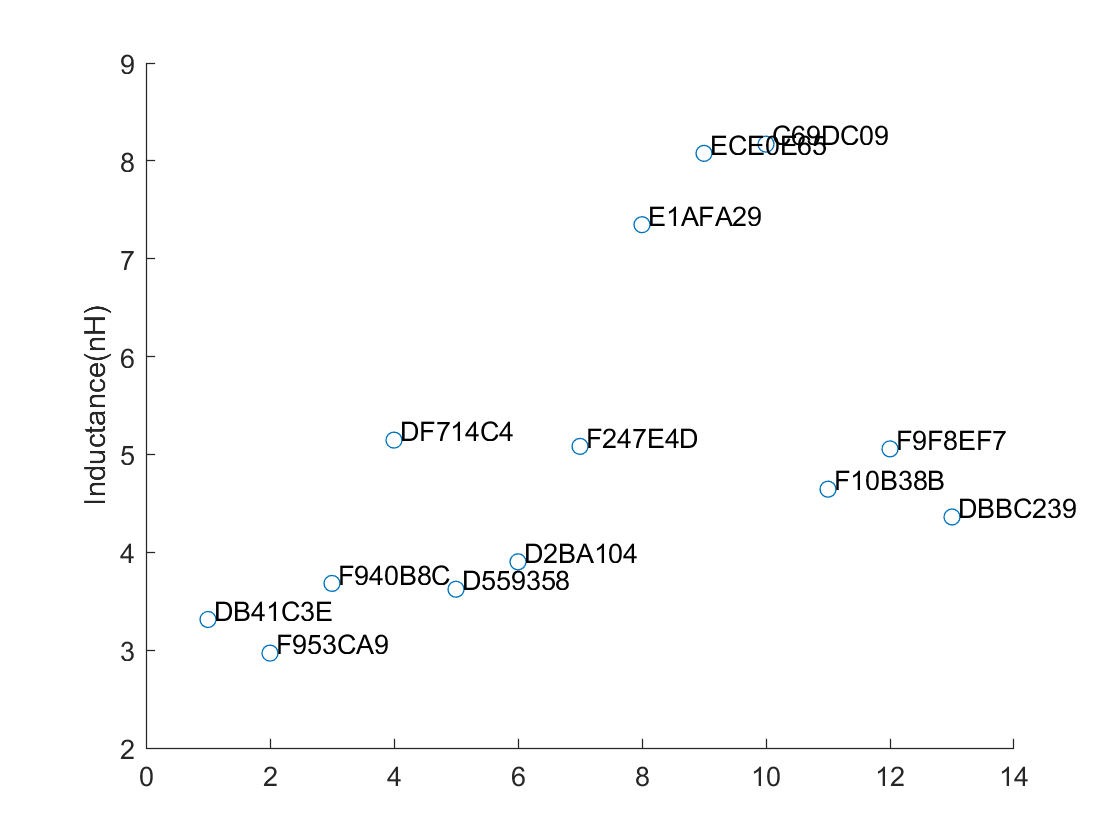

Search_Layouts = {'DB41C3E';...
    'F953CA9';...
    'F940B8C';...
    'DF714C4';...
    'D559358';...
    'D2BA104';...
    'F247E4D';...
    'E1AFA29';...
    'ECE0E65';...
    'C69DC09';...
    'F10B38B';...
    'F9F8EF7';...
    'DBBC239'};

finds = struct;
plotting_inductances = zeros(length(Search_Layouts), 1);
for i = 1:length(Search_Layouts)
    finds_entry = cellfun(@(x) ~isempty(strfind(x, Search_Layouts{i})), Loop_Inductance_Vector(:,3));
    finds.(Search_Layouts{i}) = Loop_Inductance_Vector(finds_entry, :);
    plotting_inductances(i) = finds.(Search_Layouts{i}){1};
end
dx = 0.1; dy = 0.1; % displacement so the text does not overlay the data points
figure
hold on
x = linspace(1,length(Search_Layouts),length(Search_Layouts));
y = plotting_inductances * 1e9;
scatter(x,y);
text(x+dx, y+dy, Search_Layouts);
ylabel('Inductance(nH)')
hold off

hhh = unique();
for i = 1:length(Search_Layouts)
%     Index =  i;

     Index = Search_Layouts(hhh(i));
    %     filePath = 'data/Output'
    filePath = 'data/Output'
    loadFile = sprintf('%s/%s/%s', filePath, Loop_Inductance_Vector{Index, 2}, Loop_Inductance_Vector{Index, 3});
    load(loadFile);
    for ii = 1:length(seqPair_Folders)
        if(strcmp(seqPair_Folders{ii}(1:7), Loop_Inductance_Vector{Index, 2}))
            loadfile2 = sprintf('data/gaEnsemble/%s', seqPair_Folders{ii})
            load(loadfile2)
            break
        end
    end
    
    fieldName = sprintf('n%s',Loop_Inductance_Vector{Index, 3}(1:7));
    spacing.Component_comp1(1) = save_spacing(1, 1);
    spacing.Component_comp1(2) = save_spacing(1, 2);
    spacing.Component_comp2(1) = save_spacing(2, 1);
    spacing.Component_comp2(2) = save_spacing(2, 2);
    spacing.Component_comp3(1) = save_spacing(3, 1);
    spacing.Component_comp3(2) = save_spacing(3, 2);
    [scheduler, Excel_FileID, FH2File ]= determineScheduler(1);
    %     [Netlist11, Total_Loop_Inductance] = optimization_Process_V3(G, FH2File, ...
    %         FastHenryAutomationDirectory, Excel_FileID, ...
    %         components,routingOrder, degrees, spacing , ...
    %         save_directory, Index, TTable, Matrix ...
    %         );
    
    [Netlist11, Total_Loop_Inductance, TerminalGraph, Matrix2] = optimization_Process_V4(G, FH2File, ...
        FastHenryAutomationDirectory, Excel_FileID, ...
        components,routingOrder, degrees, spacing , ...
        save_directory, Index, TTable, Matrix ...
        );
    Netlists.(fieldName) = Netlist11;
    LayoutMasks.(fieldName) = Matrix2;
    figure
    heatmap(Matrix2,'FontSize',FontSize);
    title(sprintf('Layout %s Component Masks', fieldName))
    figure
    heatmap(TerminalGraph,'FontSize',FontSize);
    title(sprintf('Layout %s Terminal Graph', fieldName))
    Layers = fields(Netlist11.Matrix);
    
    figure
    for ii =1:length(Layers)
        subplot(length(Layers), 1, ii);
        heatmap(Netlist11.Matrix.(Layers{ii}),'FontSize',FontSize);
        title(sprintf('PCB %s', Layers{ii}))
        Ax = gca;
        Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
        Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    end
    sgtitle(sprintf('Layer Stackup for %s\n Loop Inductance = %0.4f nH', ...
        fieldName , Total_Loop_Inductance*1e9), ...
        'FontSize',FontSize);
    
end

Index exceeds the number of array elements (0).